clc;
clear all;
close all;

#### IRs from empty room

% Reference room I: dataI_DG_...
               % s1r1 source position 1 and receiver position 1
               % s2r1 source position 2 and receiver position 1
               % s1r2 source position 1 and receiver position 2
% Reference room II: dataII_ISM...
% Reference room III: dataIII_DG...
% Reference room IV: dataIV_measured

#### IRs from furnished room

% Test room A: dataA_...
% Test room B: dataB_...           
% Test room C: dataC_...  
               % m1 represent absorption coefficient of furniture is 0.1
               % m2 represent absorption coefficient of furniture is 0.3
               % m3 represent absorption coefficient of furniture is 0.5
% Test room D: dataD_...
% Test room E: dataE_...
% Test room F: dataF_measured

#### Loading Data 

folders=addpath('functions_SC','data_ASC','ListeningSamples');

#### Choose one of the following

Choose ISM simluated data

% MethodEmpty=0;  %'ISM'
% load('dataII_ISM_s1r1.mat');
% IRwithoutFilter(:,:,1)=data;
% MethodFurnished=1;  %'DG'
% load('dataC_DG_s1r1m2.mat');
% IRwithoutFilter(:,:,2)=data;
% % Max frequency
% fMax=2500;
% % Center frequency of the filter 
% centerFrequenciesValid=[315  400  500    630    800   1000   1250    1600   2000];% or use centerFrequencies=getCenterFrequencies(ofb);

Choose DG simluated data

% MethodEmpty=1;  %'DG'
% load('dataI_DG_s2r1.mat');
% IRwithoutFilter(:,:,1)=data;
% MethodFurnished=1;  %'DG'
% load('dataC_DG_s2r1.mat');
% IRwithoutFilter(:,:,2)=data;
% % Max frequency
% fMax=2500;
% % Center frequency of the filter 
% centerFrequenciesValid=[315  400  500    630    800   1000   1250    1600   2000];% or use centerFrequencies=getCenterFrequencies(ofb);

Choose measured data

MethodEmpty= 2; % Measurement
load('dataIV_meas.mat');
IRwithoutFilter(:,:,1)=data;
MethodFurnished= 2;   %Measurement
load('dataF_meas.mat');
IRwithoutFilter(:,:,2)=data;
% Max frequency
fMax=6300;
% Center frequency of the filter 
centerFrequenciesValid=[315  400  500    630    800   1000   1250    1600   2000   2500   3150    4000    5000];% or use centerFrequencies=getCenterFrequencies(ofb);

#### To plot

% Which 1/3 octave band to plot
plotOctaveBand=length(centerFrequenciesValid);
% which receiver to plot
plotReceiver=1;

#### Basic parameters

% Number of the scenarios
nScenarios=size(IRwithoutFilter,3);
% Speed of sound (m/s)
c0 = 343;
% Length of the signals
nSamplesSignal=length(data);
% Sampling frequency (Hz)
fs = nSamplesSignal-1;
% Time vector
tv = (0:1:nSamplesSignal-1) * (1 / fs);
% Max order of the short signal
maxOrder=10;

#### Equation to calculate sound pressure level

spl = @(input)(20 * log10(abs(input)))+120;

#### Transducers

% Number of receivers
nReceivers = length(receiverPos);
% Distance from source to receivers
distance = vecnorm(abs(bsxfun(@minus,sourcePos,receiverPos))')';
% Calculate arrival time (s)
tDirectSec = distance ./ c0;
% Calculate arrival time (sampleNo)
nDirectSample = ceil(tDirectSec*fs);

#### To define time window (to chop signals)

meanFreePathLength = 4 * volume ./ surfaceArea;
% Approximate reflection order
order = (1./meanFreePathLength)*tv * c0 ;
% Each short signal contains one reflection 
nReflection = 1;
% Number of short signals
tMax =max(tv);
nSegment = floor(tMax/(nReflection * (meanFreePathLength/ c0)));
% Points of each short signal contains
nChoppedIR = floor(nSamplesSignal/nSegment);
% Time vector for each short signal
tSegment=nChoppedIR*(0.5:nSegment-0.5)/fs;
% Length of each segment
dSegment=nChoppedIR/fs;


#### Magnitude correction for ISM

if MethodEmpty==0
TFwithoutFilter=fft(IRwithoutFilter,[],1);
singleSideTFwithoutFilter=TFwithoutFilter(1:fs/2+1,:,:);
singleSideTFwithoutFilter(1:20,:,:)=0;
singleSideTFwithoutFilter(fMax:end,:,:)=0;
doubleSideTFwithoutFilter = [singleSideTFwithoutFilter; conj(singleSideTFwithoutFilter(end:-1:2,:,:))];
IRwithoutFilter=ifft(doubleSideTFwithoutFilter);
IRwithoutFilter(:,:,1)=IRwithoutFilter(:,:,1)./max(reshape(IRwithoutFilter(:,1,1),1,[]));
IRwithoutFilter(:,:,2)=IRwithoutFilter(:,:,2)./max(reshape(IRwithoutFilter(:,1,2),1,[]));
end


#### Source correction for Measurement

if MethodEmpty==2
IRwithoutFilterDirect=IRwithoutFilter(:,1,1);
IRwithoutFilterDirect(round(nChoppedIR):end,1)=0;
TFwithoutFilterDirect=fft(IRwithoutFilterDirect,[],1);
singleSideTFwithoutFilterDirect=TFwithoutFilterDirect(21:fMax+1,:);
TFwithoutFilter=fft(IRwithoutFilter,[],1);
singleSideTFwithoutFilter=TFwithoutFilter(21:fMax+1,:,:);
singleSideTFwithoutFilterCorrected=singleSideTFwithoutFilter./abs(singleSideTFwithoutFilterDirect);
singleSideTFwithoutFilterCorrected(1:20,:)=0;
singleSideTFwithoutFilterCorrected(fMax+2:fs/2+1,:)=0;
TFwithoutFilterCorrected = [singleSideTFwithoutFilterCorrected; conj(singleSideTFwithoutFilterCorrected(end:-1:2,:,:))];
IRwithoutFilter=ifft(TFwithoutFilterCorrected);
end

#### Wide Band (20 to highest frequency) reverberation time 

for iScenario = 1:nScenarios
for iReceiver = 1:nReceivers
    if iScenario == 1
        Method=MethodEmpty;
    else 
        Method=MethodFurnished;
    end
    [~,~,thisfullBandT30,~] = calculate_reverbtime(Method,order,nDirectSample(iReceiver), IRwithoutFilter(:,iReceiver,iScenario), nSamplesSignal,tv);
    fullBandT30(iScenario,iReceiver,:)=thisfullBandT30;
end
end
averagedfullBandT30=mean(fullBandT30,2)% Spatial averaging T30

averagedfullBandT30 =     1.3676
    1.2930


tPlot=tv(nChoppedIR*31);
schroederFrequency = (0.33 * (averagedfullBandT30 * c0.^3 / volume).^0.5)% Schroeder frequency (Hz)

schroederFrequency =   287.4616
  279.5097


#### To define filter

% Number of 1/3 octave bands 
nOctaveBands=length(centerFrequenciesValid);
% Filter    
ofb = octaveFilterBank("1/3 octave",fs,FilterOrder=10);
bandpassFilters = freqz(ofb,NFFT=fs/2+1); 
bandpassFiltersValid=abs(bandpassFilters(:,12:12+(nOctaveBands-1)));

#### To filter IRs

for iScenario = 1:nScenarios
for iReceiver = 1:nReceivers
for iOctaveBand = 1:nOctaveBands        
         thisIRfiltered=calculate_filteredSignal(IRwithoutFilter(:,iReceiver,iScenario),bandpassFiltersValid(:,iOctaveBand),nSamplesSignal);
         IRfiltered(iScenario,iReceiver,iOctaveBand,:)=thisIRfiltered;
end 
end
end

#### Modify IRs to make the first mean free path only contains direct sound

% modifyDistance=mean(distance)-meanFreePathLength;
% nmodifyDistance = ceil(modifyDistance ./ c0*fs);
% nmodifyDistance=nmodifyDistance+61;
% if nmodifyDistance>=0  % move forward
% IRfiltered(:,:,:,1:end-nmodifyDistance+1)=IRfiltered(:,:,:,nmodifyDistance:end);
% IRfiltered(:,:,:,end-nmodifyDistance+2:end)=0;
% else   % move backward
% IRfiltered=cat(4,zeros(2,nReceivers,nOctaveBands,abs(nmodifyDistance)),IRfiltered(:,:,:,1:end+nmodifyDistance));
% end

#### To chop signals

% Order vector
nOrder=0:maxOrder;
% To chop signals using a rectangular window
choppedIRs=cat(4,reshape(IRfiltered(:,:,:,1:(maxOrder+1)*nChoppedIR),nScenarios,nReceivers,nOctaveBands,nChoppedIR,(maxOrder+1)),zeros(nScenarios,nReceivers,nOctaveBands,fs/10-nChoppedIR,maxOrder+1));
% Frequency resolution of the chopped signal
resFrequency=1/(length(choppedIRs)/fs);
% Number of frequency points
nFrequency=fMax/resFrequency+1;
% Frequency vector of the chopped signal
fChopped=0:resFrequency:(nFrequency-1)*resFrequency;
% Fourier Transform 
choppedSTFs=fft(choppedIRs,[],4)/(fs/10);% symmetric transfer function
choppedTFs=choppedSTFs(:,:,:,1:nFrequency,:);% single side transfer function

## Average Scattering Coefficients (ASCs)

#### To calculate coherence

% Transfer function for empty room
Fx=choppedTFs(1,:,:,:,:,:);
% Transfer function for furnished room
Fy=choppedTFs(2,:,:,:,:,:);
% Power spectral densities
Sxx = (abs(Fx)).^2;
Syy = (abs(Fy)).^2;
% Cross power spectral densities
Sxy = Fx .* conj(Fy);
% To calculate coherence
SXX = abs(mean(Sxx, 2));
SYY = abs(mean(Syy, 2));
SXY = abs(mean(Sxy, 2));
coherenceCoefsAllFrequency = SXY./((SXX .* SYY).^0.5);
% Frequency averaged
coherenceCoefs=reshape(mean(coherenceCoefsAllFrequency,4),nOctaveBands,(maxOrder+1));

#### To extract ASCs

for iOctaveBand=1:nOctaveBands
for iScatteringCoef=1:1000
    % Estimated ASCs from 0 to 1
    thisScatteringCoef=0.001*iScatteringCoef; 
    % Calculated coherence curve using the estimated ESCs
    thiscoherenceCurve=[((1 -thisScatteringCoef).^(nOrder(1:maxOrder+1))).^0.5];
    % Calculate the difference between real and estimated coherence curves
    deltaCoherenceCurve(iScatteringCoef,:)=sum(abs(thiscoherenceCurve-coherenceCoefs(iOctaveBand,:)).^2);
end
% Find the best fitted value of ASC
ASC(iOctaveBand)=0.001*(find(deltaCoherenceCurve==min(deltaCoherenceCurve))); 
% To analyze the effects of ASCs, ASCs can be adjusted by: 
% ASC(iOctaveBand)=0.9;
%Coherence curves until 10th order
predictedCoherenceCurve(iOctaveBand,:)  =  [((1 -  ASC(iOctaveBand)).^nOrder(1:maxOrder+1)).^0.5];
% Coherence envelope
coherentEnvelope(iOctaveBand,:)  =  [ones(1,nChoppedIR),((1 -  ASC(iOctaveBand)).^order(1:end-nChoppedIR)).^0.5]; %[((1 -  ASC(iOctaveBand)).^order).^0.5]; 
% Incoherence envelope
incoherentEnvelope(iOctaveBand,:) = (1-(coherentEnvelope(iOctaveBand,:)).^2).^0.5;
end


#### Plot ASC

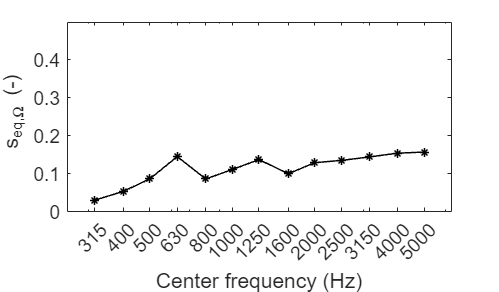

figure;
plot(centerFrequenciesValid, ASC, "k*-", 'LineWidth', 1)
set(gca,'XScale','log');
xticks(centerFrequenciesValid)
xlabel('Center frequency (Hz)');ylabel(' s_{eq,\Omega} (-)');
plot_figures(250,fMax,0,0.5)

#### Plot coherence coefficent curves

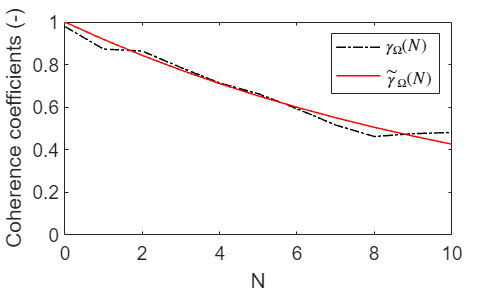

figure;
plot(nOrder,coherenceCoefs(plotOctaveBand,:),"k-.",'LineWidth',1);
hold on;
plot(nOrder,predictedCoherenceCurve(plotOctaveBand,:),"r",'LineWidth',1);
legend({'$\gamma_{\Omega}(N)$','$\tilde{\gamma}_{\Omega}(N)$'}, 'Interpreter', 'latex');
xlabel('N');ylabel('Coherence coefficients (-)');
plot_figures(0,maxOrder,0,1)

#### Decay curve for 1/3 octave bands

for iScenario = 1:nScenarios
    if iScenario == 1
        Method=MethodEmpty;
    else 
        Method=MethodFurnished;
    end    
for iReceiver = 1:nReceivers
for iOctaveBand = 1:nOctaveBands
 [~,~,~,thisDecayCurvefitted] = calculate_reverbtime(Method,order,nDirectSample(iReceiver), IRfiltered(iScenario,iReceiver,iOctaveBand,:), nSamplesSignal,tv);
decayCurvesfitted(iScenario,iReceiver,iOctaveBand,:)=thisDecayCurvefitted;
end
end
end
% Spatial averaged values (Pa)
averagedDecayCurvesfitted=reshape(mean(10.^((decayCurvesfitted-120)/20),2),nScenarios,nOctaveBands,[]);
% Spatial averaged values (dB)
averagedDecayCurvesfittedSPL=spl(averagedDecayCurvesfitted);

#### Absorption Envelope

for iScenario = 1:nScenarios
    if iScenario == 1
        Method=MethodEmpty;
    else 
        Method=MethodFurnished;
    end  
if Method==0  %For ISM, the decay curve is calculated from absorption coeffcient
 absorptionCoef=0.1118;
for iOctaveBand=1:nOctaveBands
absorptionEnv(iScenario,iOctaveBand,:) = ((1 - absorptionCoef).^(order)).^0.5;
end

else if Method==1   %For DG, the decay curve is not linear
for iOctaveBand=1:nOctaveBands
% decay curve
thisaveragedDecayCurvesfitted=reshape(averagedDecayCurvesfitted(iScenario,iOctaveBand,:),1,[]);
% Absorption Envelope
absorptionEnv(iScenario,iOctaveBand,:)=thisaveragedDecayCurvesfitted/max(thisaveragedDecayCurvesfitted);
end

else   % for measurement, the decay curve is linear
for iOctaveBand=1:nOctaveBands
% decay curve
thisaveragedDecayCurvesfitted=reshape(averagedDecayCurvesfittedSPL(iScenario,iOctaveBand,:),1,[]);
p = polyfit(tv,thisaveragedDecayCurvesfitted,1);
averagedT60=60/(-p(1));
% absorption Coefficients
absorptionCoef= (1 - exp(log(10^-6)*meanFreePathLength./(averagedT60 * c0 )));
% Absorption Envelope
absorptionEnv(iScenario,iOctaveBand,:) = ((1 - absorptionCoef).^(order)).^0.5;
end

end
end
end

#### To find the magnitude for the envelopes

% Saptial averaged IRs
IRfiltered_SaptialAverage=reshape(mean((abs(IRfiltered(1,:,:,1:(maxOrder)*nChoppedIR))).^2,2),nOctaveBands,[]);
% Calculate energy of IRs
IRfiltered_energy=sum(IRfiltered_SaptialAverage,2);
% Calculate energy of envelopes
absorptionEnvelope_Energy=sum(absorptionEnv(1,:,1:(maxOrder)*nChoppedIR).^2,3)';
% To find the magnitude for the envelopes make the energy of the envelopes
% same with energy of IRs
envMagnitude=(IRfiltered_energy./absorptionEnvelope_Energy).^0.5';
% Apply this magnitude in absorption envelope
absorptionEnvScaled=reshape(envMagnitude,1,nOctaveBands,1).*absorptionEnv;

#### Plot IR and absorption envelope  [FIG.11(a)]

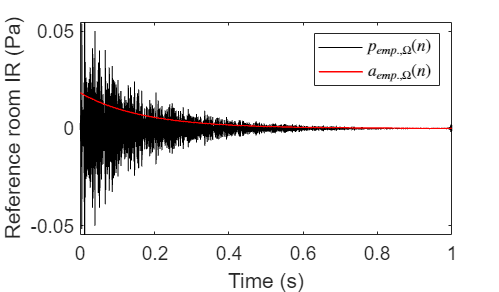

tPlot=min(averagedfullBandT30(2),1);

figure;
plot(tv,reshape(IRfiltered(1,plotReceiver,plotOctaveBand,:),1,[]),"k",'LineWidth',0.5);
hold on;
plot(tv,reshape(absorptionEnvScaled(1,plotOctaveBand,:),1,[]),"r",'LineWidth',1);
legend('${{p}_{emp.,\Omega}}(n)$','${a}_{emp.,\Omega}(n)$', 'Interpreter', 'latex')
xlabel('Time (s)');ylabel('Reference room IR (Pa)');
plot_figures(0,tPlot,-envMagnitude(plotOctaveBand)*3, envMagnitude(plotOctaveBand)*3)

#### Plot absorption envelopes of empty room and furnished room                 

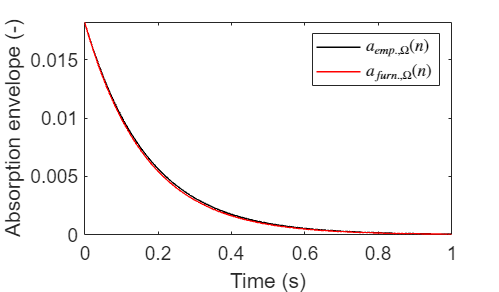

figure
plot(tv,reshape(absorptionEnvScaled(1,plotOctaveBand,:),1,[]),"k",'LineWidth',1);
hold on
plot(tv,reshape(absorptionEnvScaled(2,plotOctaveBand,:),1,[]),"r",'LineWidth',1);
legend('${a}_{emp.,\Omega}(n)$','${a}_{furn.,\Omega}(n)$', 'Interpreter', 'latex')
xlabel('Time (s)');ylabel('Absorption envelope (-)');
plot_figures(0,tPlot,0, envMagnitude(plotOctaveBand))

#### Eliminate the impact of absorption 

absorptionCorrection=reshape(absorptionEnv(2,:,:)./absorptionEnv(1,:,:),nOctaveBands,[]);

#### Specular and non-specular envelopes

specularEnvelope = coherentEnvelope.* reshape(absorptionEnvScaled(2,:,:),nOctaveBands,[]);
nonspecularEnvelope = incoherentEnvelope.* reshape(absorptionEnvScaled(2,:,:),nOctaveBands,[]);

#### Plot specular and non-specular envelopes             [FIG.11(b)]

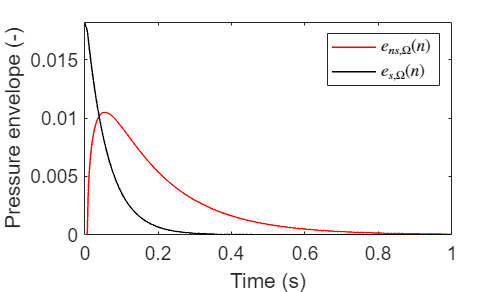

figure;
plot(tv,nonspecularEnvelope(plotOctaveBand,:),"r",'LineWidth',1)
hold on
plot(tv,specularEnvelope(plotOctaveBand,:),"k",'LineWidth',1)
legend('${e}_{ns,\Omega}(n)$','${e}_{s,\Omega}(n)$', 'Interpreter', 'latex')
xlabel('Time (s)');ylabel('Pressure envelope (-)');
plot_figures(0,tPlot,0, envMagnitude(plotOctaveBand))

## Hybrid model

for iReceiver = 1:nReceivers
% Non-specular part generated by noise
noise = (3^0.5)*(2 * rand(1, nSamplesSignal));
for iOctaveBand = 1:nOctaveBands
%  IRs of empty room corrected by absorption 
IRfilteredEmptyCorrected =reshape(IRfiltered(1,iReceiver,iOctaveBand,:),1,[]).*absorptionCorrection(iOctaveBand,:);
%  IRs of furnished room
IRfilteredFurnished = reshape(IRfiltered(2,iReceiver,iOctaveBand,:),1,[]);
% Specular part
thisSpecularPart = IRfilteredEmptyCorrected .* coherentEnvelope(iOctaveBand,:);
noiseFiltered=calculate_filteredSignal(noise',bandpassFiltersValid(:,iOctaveBand),nSamplesSignal);
% Make the energy (stand deviation) of this noise into 1
% thisNoiseCorrection = ((sum((abs(noise)).^2) / sum((abs(noiseFiltered)).^2)))^0.5;
thisNoiseCorrection=1/((mean((abs(noiseFiltered)).^2)).^0.5);
thisNoiseFilteredCorrected = thisNoiseCorrection * noiseFiltered;
thisNonSpecularPartPredicted = (thisNoiseFilteredCorrected' .* nonspecularEnvelope(iOctaveBand,:));
%  Predicted Furnished room IRs
thisIRfilteredPredicted = thisNonSpecularPartPredicted + thisSpecularPart;
%  Store data in matrix
specularPart(iReceiver,iOctaveBand, :)=thisSpecularPart;
nonspecularPartTruth(iReceiver,iOctaveBand, :)=IRfilteredFurnished - thisSpecularPart;
nonspecularPartPredicted(iReceiver,iOctaveBand, :)=thisNonSpecularPartPredicted;
IRfilteredFurnishedPredicted(iReceiver,iOctaveBand, :)=thisIRfilteredPredicted;
end
end

#### Plot specular part             [FIG.11(c)]

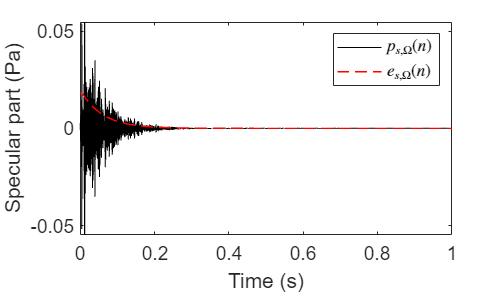

figure;
plot(tv,reshape(specularPart(plotReceiver,plotOctaveBand,:),1,[]),"k",'LineWidth',0.5);
hold on
plot(tv,specularEnvelope(plotOctaveBand,:),"r--",'LineWidth',1)
legend('${{p}_{s,\Omega}}(n)$','${e}_{s,\Omega}(n)$', 'Interpreter', 'latex')
xlabel('Time (s)');ylabel('Specular part (Pa)');
plot_figures(0,tPlot,-envMagnitude(plotOctaveBand)*3, envMagnitude(plotOctaveBand)*3)

#### Plot real non-specular part 

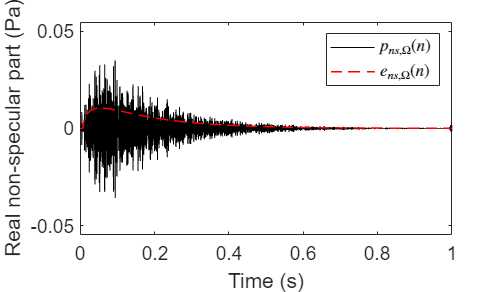

figure;
plot(tv,reshape(nonspecularPartTruth(plotReceiver,plotOctaveBand,:),1,[]),"k",'LineWidth',0.5);
hold on
plot(tv,nonspecularEnvelope(plotOctaveBand,:),"r--",'LineWidth',1)
legend('${{p}_{ns,\Omega}}(n)$','${e}_{ns,\Omega}(n)$', 'Interpreter', 'latex')
xlabel('Time (s)');ylabel('Real non-specular part (Pa)');
plot_figures(0,tPlot,-envMagnitude(plotOctaveBand)*3, envMagnitude(plotOctaveBand)*3)

#### Plot generated non-specular part         [FIG.11(d)]

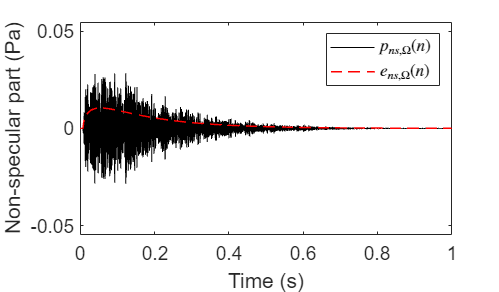

figure;
plot(tv,reshape(nonspecularPartPredicted(plotReceiver,plotOctaveBand,:),1,[]),"k",'LineWidth',0.5);
hold on
plot(tv,nonspecularEnvelope(plotOctaveBand,:),"r--",'LineWidth',1)
legend('${{p}_{ns,\Omega}}(n)$','${e}_{ns,\Omega}(n)$', 'Interpreter', 'latex')
xlabel('Time (s)');ylabel('Non-specular part (Pa)');
plot_figures(0,tPlot,-envMagnitude(plotOctaveBand)*3, envMagnitude(plotOctaveBand)*3)

#### Plot IR (Pa) of 1/3 octave bands                [FIG.4]

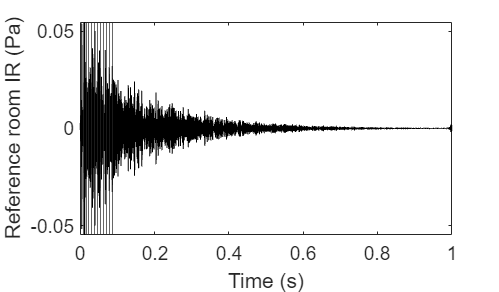

% IR of empty room
figure;
for iSegment=1:maxOrder+1
    hold on
    xline(iSegment*nChoppedIR/fs,'LineWidth',0.3)
end
plot(tv,reshape(IRfiltered(1,plotReceiver,plotOctaveBand,:),1,[]),"k",'LineWidth',0.5);
xlabel('Time (s)');ylabel( 'Reference room IR (Pa)');
plot_figures(0,tPlot,-envMagnitude(plotOctaveBand)*3, envMagnitude(plotOctaveBand)*3)

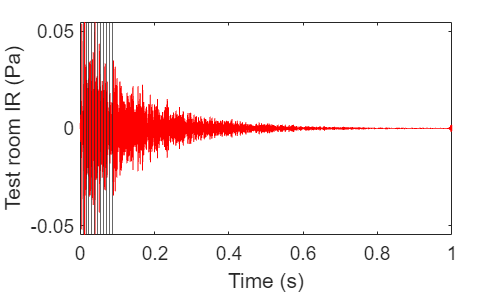

% Ground truth IR of furnished room
figure;
for iSegment=1:maxOrder+1
    hold on
    xline(iSegment*nChoppedIR/fs,'LineWidth',0.3)
end
hold on
plot(tv,reshape(IRfiltered(2,plotReceiver,plotOctaveBand,:),1,[]),"r",'LineWidth',0.5);
xlabel('Time (s)');ylabel( 'Test room IR (Pa)');
plot_figures(0,tPlot,-envMagnitude(plotOctaveBand)*3, envMagnitude(plotOctaveBand)*3)

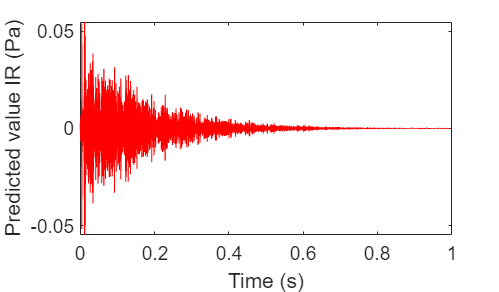

% Predicted IR of furnished room
figure;
plot(tv,reshape(IRfilteredFurnishedPredicted(plotReceiver,plotOctaveBand,:),1,[]),"r",'LineWidth',0.5);
xlabel('Time (s)');ylabel('Predicted value IR (Pa)');
plot_figures(0,tPlot,-envMagnitude(plotOctaveBand)*3, envMagnitude(plotOctaveBand)*3)

#### Plot IR (dB) of 1/3 octave bands              [FIG.12]

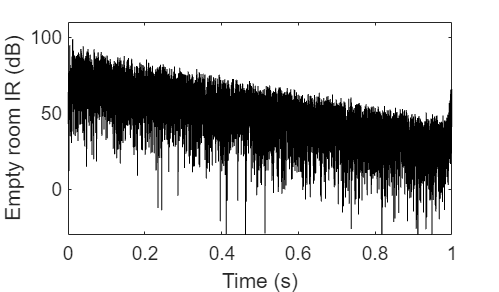

tPlot=min(averagedfullBandT30(2),1);

%  IR of reference room
figure;
plot(tv,spl(reshape(IRfiltered(1,plotReceiver,plotOctaveBand,:),1,[])),"k",'LineWidth',0.1);
xlabel('Time (s)');ylabel('Empty room IR (dB)');
plot_figures(0,tPlot,-30, 110)

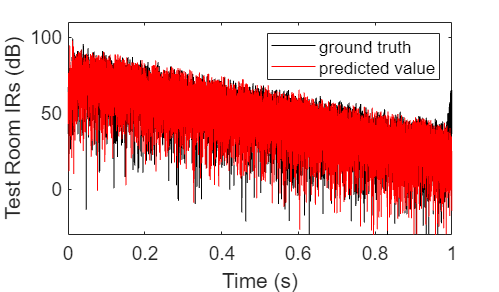

% Ground truth IR of furnished room
figure;
plot(tv,spl(reshape(IRfiltered(2,plotReceiver,plotOctaveBand,:),1,[])),"k",'LineWidth',0.1);
hold on
plot(tv,spl(reshape(IRfilteredFurnishedPredicted(plotReceiver,plotOctaveBand,:),1,[])),"r",'LineWidth',0.1);
legend('ground truth','predicted value')
xlabel('Time (s)');ylabel('Test Room IRs (dB)');
plot_figures(0,tPlot,-30, 110)

## Evaluation

for iReceiver = 1:nReceivers
% Index for direct sound
nStart=nDirectSample(iReceiver);
for iOctaveBand = 1:nOctaveBands
% Ground truth IR
thisIRfilteredFurnishedTruth = reshape(IRfiltered(2,iReceiver,iOctaveBand,:),1,[]);
[thisEDTTruth,thisT20Truth,thisT30Truth,~] = calculate_reverbtime(MethodFurnished,order,nStart, thisIRfilteredFurnishedTruth, nSamplesSignal,tv);
thisEnergyTruth=calculate_energy(thisIRfilteredFurnishedTruth);
% Store data in matrix
EDTTruth(iReceiver,iOctaveBand,:)=thisEDTTruth;
T20Truth(iReceiver,iOctaveBand,:)=thisT20Truth;
T30Truth(iReceiver,iOctaveBand,:)=thisT30Truth;
EnergyTruth(iReceiver,iOctaveBand,:)=thisEnergyTruth;
% Predicted IR
thisIRfilteredPredicted=reshape(IRfilteredFurnishedPredicted(iReceiver,iOctaveBand,:),1,[]);
[thisEDTPredicted,thisT20Predicted,thisT30Predicted,~] = calculate_reverbtime(MethodFurnished,order, nStart, thisIRfilteredPredicted, nSamplesSignal,tv);
thisEnergyPredicted=calculate_energy(thisIRfilteredPredicted);
% Store data in matrix
EDTPredicted(iReceiver,iOctaveBand,:)=thisEDTPredicted;
T20Predicted(iReceiver,iOctaveBand,:)=thisT20Predicted;
T30Predicted(iReceiver,iOctaveBand,:)=thisT30Predicted;
EnergyPredicted(iReceiver,iOctaveBand,:)=thisEnergyPredicted;
end
end

#### Error of the spatial averaged EDT, T20, T30

% Percentage error of reverberation time
meanerrorEDT=(mean(abs(EDTPredicted-EDTTruth)./EDTTruth))*100 ;
meanerrorT30=(mean(abs(T30Predicted-T30Truth)./T30Truth))*100 ;
% Error of energy (dB)
meanerrorE=mean(abs(EnergyPredicted-EnergyTruth));

#### Plot mean error in 1/3 octave band     

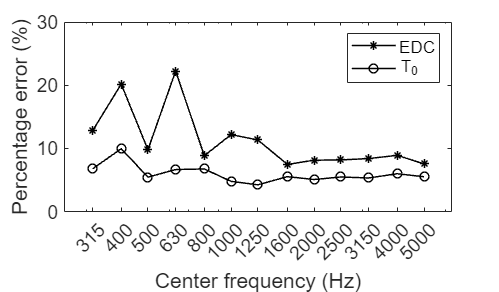

figure;
plot(centerFrequenciesValid, meanerrorEDT, "k*-", 'LineWidth', 1)
hold on
plot(centerFrequenciesValid, meanerrorT30, "ko-", 'LineWidth', 1)
legend('EDC','T_3_0')
set(gca,'XScale','log');
xticks(centerFrequenciesValid)
xlabel('Center frequency (Hz)');
ylabel('Percentage error (%)');
plot_figures(250,fMax,0, 30)

#### Plot error bar in 1/3 octave band         [FIG.13]

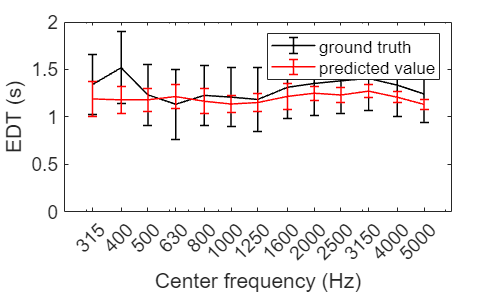

figure;
errorbar(centerFrequenciesValid,mean(EDTTruth),std(EDTTruth), "k-", 'LineWidth', 1)
hold on
errorbar(centerFrequenciesValid,mean(EDTPredicted),std(EDTPredicted), "r-", 'LineWidth', 1)
set(gca,'XScale','log');
legend('ground truth','predicted value')
xticks(centerFrequenciesValid)
xlabel('Center frequency (Hz)');ylabel('EDT (s)');
plot_figures(250,fMax,0, 2)

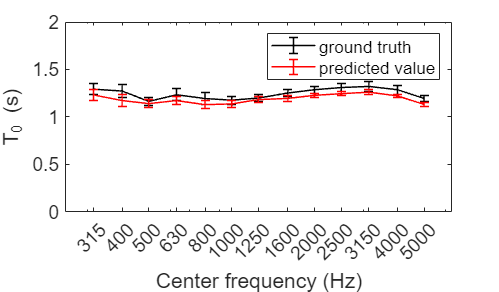

figure;
errorbar(centerFrequenciesValid,mean(T30Truth),std(T30Truth), "k-", 'LineWidth', 1)
hold on
errorbar(centerFrequenciesValid,mean(T30Predicted),std(T30Predicted), "r-", 'LineWidth', 1)
set(gca,'XScale','log');
legend('ground truth','predicted value')
xticks(centerFrequenciesValid)
xlabel('Center frequency (Hz)');ylabel('T_3_0 (s)');
plot_figures(250,fMax,0, 2)

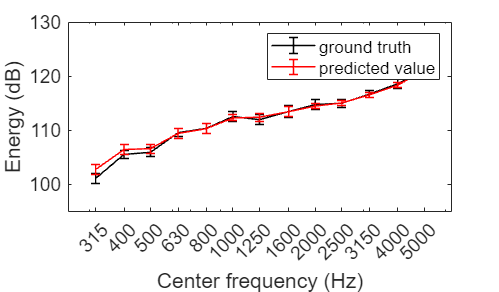

figure;
errorbar(centerFrequenciesValid,mean(EnergyTruth),std(EnergyTruth), "k-", 'LineWidth', 1)
hold on
errorbar(centerFrequenciesValid,mean(EnergyPredicted),std(EnergyPredicted), "r-", 'LineWidth', 1)
set(gca,'XScale','log');
legend('ground truth','predicted value')
xticks(centerFrequenciesValid)
xlabel('Center frequency (Hz)');ylabel('Energy (dB)'); 
plot_figures(250,fMax,95, 130)

## To check scattering degree in the predicted sound field

#### To calculate ASCs

% Empty room IRs
IRfiltered_P(1,:,:,:)=IRfiltered(1,:,:,:);
% Predicted furnished room IRs
IRfiltered_P(2,:,:,:)=IRfilteredFurnishedPredicted;
% To calculate ASCs of this predicted sound fields
[ASC_P] = calculate_ASC(fs,maxOrder,nOrder,nScenarios,nReceivers,nOctaveBands,nChoppedIR,nFrequency,IRfiltered_P);

####  Plot ASC     [FIG.14]

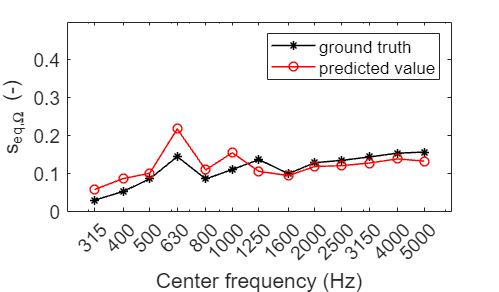

figure;
plot(centerFrequenciesValid, ASC, "k*-", 'LineWidth', 1)
hold on
plot(centerFrequenciesValid, ASC_P, "ro-", 'LineWidth', 1)
legend('ground truth','predicted value')
set(gca,'XScale','log');
xticks(centerFrequenciesValid)
xlabel('Center frequency (Hz)');
ylabel('s_{eq,\Omega} (-)');
plot_figures(250,fMax,0, 0.5)

### Wide band IRs of furnished room

% Wide band Ground truth IRs
IRsWideBand=reshape(sum(IRfiltered,3),nScenarios,nReceivers,nSamplesSignal);
IRsEmpty=reshape(IRsWideBand(1,:,:),nReceivers,nSamplesSignal)';
IRsFurnished.GroundTruth=reshape(IRsWideBand(2,:,:),nReceivers,nSamplesSignal)';
% Wide band predicted IRs
IRsFurnished.Predict=reshape(sum(IRfilteredFurnishedPredicted,2),nReceivers,nSamplesSignal)';
% save('IRsFurnished.mat', "IRsFurnished","receiverPos","sourcePos","volume","surfaceArea")

#### Wide band results evaluation-kurtosis

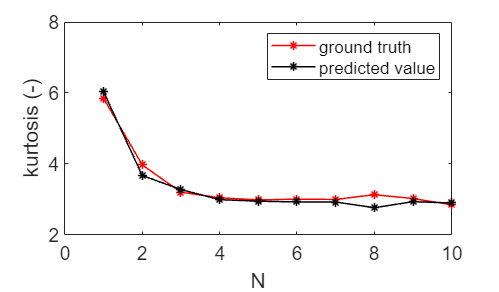

for iOrder=1:maxOrder
nStart=nChoppedIR*iOrder+1;
nEnd=nChoppedIR*(iOrder+1);
for iReceiver=1:nReceivers
IRsFT=IRsFurnished.GroundTruth(:,iReceiver);
IRsFP=IRsFurnished.Predict(:,iReceiver);
kurtosisFT(iOrder,iReceiver)= kurtosis(IRsFT(nStart:nEnd),0);
kurtosisFP(iOrder,iReceiver)= kurtosis(IRsFP(nStart:nEnd),0);
end
end

figure
plot(1:maxOrder,mean(kurtosisFT,2),"r-*",'LineWidth',1)
hold on
plot(1:maxOrder,mean(kurtosisFP,2),"k-*",'LineWidth',1)
legend({'ground truth','predicted value'});
xlabel('N');ylabel('kurtosis (-)');
plot_figures(0,10,2,8)

#### Wide band results evaluation-EDT,T30,Energy

for iReceiver = 1:nReceivers
% Index for direct sound
nStart=nDirectSample(iReceiver);
% Ground truth IR
thisIRfilteredFurnishedTruth = reshape(IRsFurnished.GroundTruth(:,iReceiver),1,[]);
[thisEDTTruth,thisT20Truth,thisT30Truth,~] = calculate_reverbtime(MethodFurnished,order,nStart, thisIRfilteredFurnishedTruth, nSamplesSignal,tv);
thisEnergyTruth=calculate_energy(thisIRfilteredFurnishedTruth);
% Store data in matrix
EDTTruthWideBand(iReceiver,:)=thisEDTTruth;
T20TruthWideBand(iReceiver,:)=thisT20Truth;
T30TruthWideBand(iReceiver,:)=thisT30Truth;
EnergyTruthWideBand(iReceiver,:)=thisEnergyTruth;
% Predicted IR
thisIRfilteredPredicted=reshape(IRsFurnished.Predict(:,iReceiver),1,[]);
[thisEDTPredicted,thisT20Predicted,thisT30Predicted,~] = calculate_reverbtime(MethodFurnished,order, nStart, thisIRfilteredPredicted, nSamplesSignal,tv);
thisEnergyPredicted=calculate_energy(thisIRfilteredPredicted);
% Store data in matrix
EDTPredictedWideBand(iReceiver,:)=thisEDTPredicted;
T20PredictedWideBand(iReceiver,:)=thisT20Predicted;
T30PredictedWideBand(iReceiver,:)=thisT30Predicted;
EnergyPredictedWideBand(iReceiver,:)=thisEnergyPredicted;
end


#### Error of the spatial averaged EDT, T30, Energy

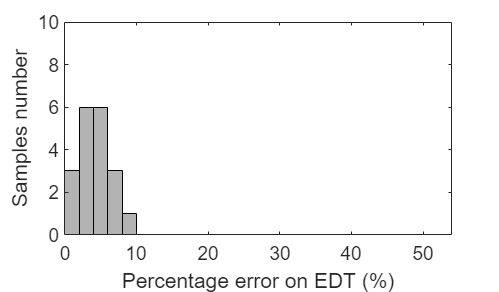

% Percentage error of reverberation time
errorEDTWideBand=abs(EDTPredictedWideBand-EDTTruthWideBand)./EDTTruthWideBand*100; 
meanerrorEDTWideBand=(mean(errorEDTWideBand));
errorT30WideBand=abs(T30PredictedWideBand-T30TruthWideBand)./T30TruthWideBand*100;
meanerrorT30WideBand=(mean(errorT30WideBand)); 
% Error of energy (dB)
errorEWideBand=(EnergyPredictedWideBand-EnergyTruthWideBand);
meanerrorEWideBand=mean(errorEWideBand);


figure;
histogram(errorEDTWideBand,'BinWidth',2, 'FaceColor', '[0.5 0.5 0.5]');
xlabel('Percentage error on EDT (%)');
ylabel('Samples number');
set(gca, 'FontSize', 13);
plot_figures(0,round(max(errorEDTWideBand)/2)*2,0, nReceivers/2)

length(find(errorT30WideBand<=10))/252

ans = 0.0794

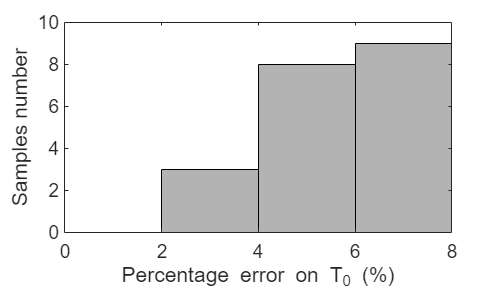

figure;
histogram(errorT30WideBand,'BinWidth',2,'FaceColor', '[0.5 0.5 0.5]');
xlabel('Percentage error on T_3_0 (%)');
ylabel('Samples number');
set(gca, 'FontSize', 13);
plot_figures(0,round(max(errorT30WideBand)/2)*2,0, nReceivers/2)

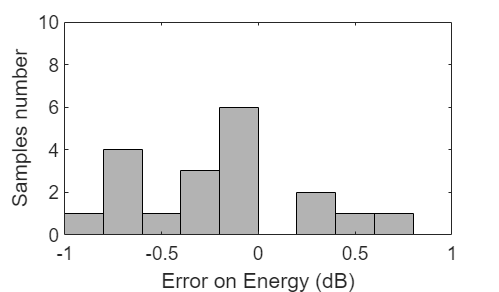

figure;
histogram(errorEWideBand,'BinWidth',0.2, 'FaceColor', '[0.5 0.5 0.5]');
xlabel('Error on Energy (dB)');
ylabel('Samples number');
set(gca, 'FontSize', 13);
plot_figures(round(min(errorEWideBand)/0.2)*0.2,round(max(errorEWideBand)/0.2)*0.2,0,nReceivers/2)

#### Listening IRs

plotReceiver=1;
% ground truth
thisIR_T=reshape(IRsFurnished.GroundTruth(1:(nSamplesSignal-1)/10*9,plotReceiver),1,[]);
% Predict value
thisIR_P=reshape(IRsFurnished.Predict(1:(nSamplesSignal-1)/10*9,plotReceiver),1,[]);

% ground truth
convSig_T = thisIR_T;
convSig_T_Normalized = convSig_T/max(abs(convSig_T));
sound(convSig_T_Normalized, fs);
% Predict value
convSig_P = thisIR_P;
convSig_P_Normalized = convSig_P/max(abs(convSig_P));
sound(convSig_P_Normalized, fs);

#### Listening female voice

[dryaudio_femalevoice, FS] = audioread("femalevoice.wav");
sound(dryaudio_femalevoice, FS);

% ground truth
convSig_T = cconv(dryaudio_femalevoice, thisIR_T)/FS;
convSig_T_Normalized = convSig_T/max(abs(convSig_T));
sound(convSig_T_Normalized, FS);
% Predict value
convSig_P = cconv(dryaudio_femalevoice, thisIR_P)/FS;
convSig_P_Normalized = convSig_P/max(abs(convSig_P));
sound(convSig_P_Normalized, FS);


% audiowrite('GroundTruth_femaleVoice.wav',convSig_T_Normalized,FS)
% audiowrite('ASC01_HybridModel_femaleVoice.wav',convSig_P_Normalized,FS)

#### Listening male voice

[dryaudio_malevoice, FS] = audioread("malevoice.wav");
sound(dryaudio_malevoice, FS);

% ground truth
convSig_T = cconv(dryaudio_malevoice, thisIR_T)/FS;
convSig_T_Normalized = convSig_T/max(abs(convSig_T));
sound(convSig_T_Normalized, FS);
% Predict value
convSig_P = cconv(dryaudio_malevoice, thisIR_P)/FS;
convSig_P_Normalized = convSig_P/max(abs(convSig_P));
sound(convSig_P_Normalized, FS);


% audiowrite('GroundTruth_maleVoice.wav',convSig_T_Normalized,FS)
% audiowrite('ASC01_HybridModel_maleVoice.wav',convSig_P_Normalized,FS)